# Stock Data - Understanding Invariance

In this exercise, you will create two animated histograms that show the distribution of stock prices and returns for Magnum Hunter Resources Corporation for a moving 500-day period. You should notice that whilst the distribution of the prices changes over time, the returns distribution changes very little.

## 1.

Load data from `stockData_allCapSizes.mat`.

load stockData_allCapSizes.mat

## 2.

Extract the daily prices for Magnum Hunter Resources Corporation (ticker: `MHR`), and calculate the returns using:

`MHRrets``= diff(log(``MHRprices``))`

MHRprices = stockPrices.MHR;
MHRrets = diff(log(MHRprices))

MHRrets =          0
   -0.0328
    0.0328
   -0.0245
    0.0082
   -0.0165
   -0.0426
         0
   -0.1298
    0.0099


## 3.

Create two histograms that show the distribution of the MHR prices and the MHR returns for the first 500 days on two subplots. Use bin edges that range from the minimum to the maximum of the prices or returns.

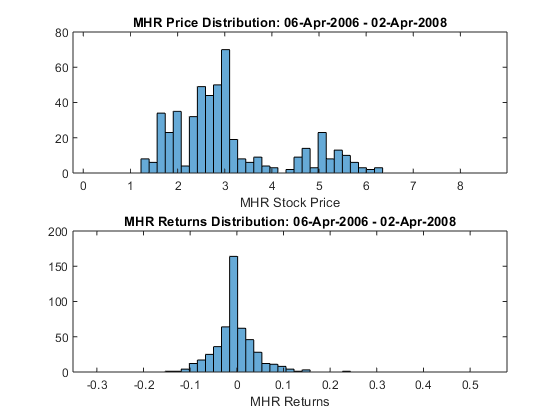

date = stockPrices.Date;
pbins = linspace(min(MHRprices), max(MHRprices),50);
rbins = linspace(min(MHRrets), max(MHRrets), 50);

figure
subplot(2,1,1)
histogram(MHRprices(1:500), pbins)
title(['MHR Price Distribution: ',...
    char(date(1)), ' - ', char(date(500))])
xlabel('MHR Stock Price')

subplot(2,1,2)
histogram(MHRrets(1:500), rbins)
title(['MHR Returns Distribution: ',...
    char(date(1)), ' - ', char(date(500))])
xlabel('MHR Returns')

## 4.

Place the code used to create the histograms in step 3 inside a for-loop and edit it so that the histograms show 500-day moving windows. For example, iteration 1 shows data for days 1 to 500, iteration 2 shows data for days 2 to 501 and so on. **Hint:** Use `drawnow` to update the graphics on each iteration.

date = stockPrices.Date;
window = 500;
pbins = linspace(min(MHRprices), max(MHRprices),50);
rbins = linspace(min(MHRrets), max(MHRrets), 50);

figure('Visible','on') %start animation in separate figure window
for k = 1:length(MHRrets)-window
    subplot(2,1,1)
    pricesInWindow = MHRprices(k+1:k+window+1, :);
    histogram(pricesInWindow, pbins)
    title(['MHR Price Distribution: ',...
        char(date(k+1)), ' - ', char(date(k+window))])
    xlabel('MHR Stock Price')
    
    subplot(2,1,2)
    histogram(MHRrets(k:k+window, :), rbins)
    title(['MHR Returns Distribution: ',...
        char(date(k+1)), ' - ', char(date(k+window))])
    xlabel('MHR Returns')
    drawnow
end